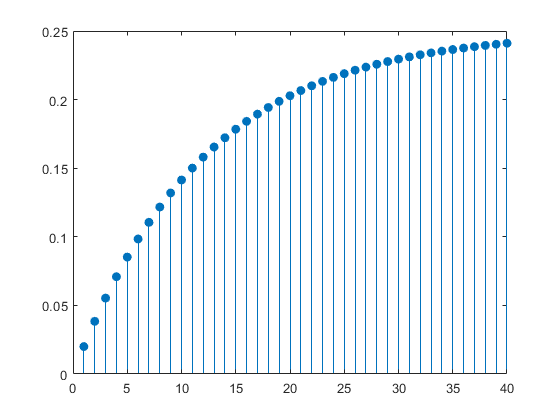

%1c
u = @(t) t>=0;  
y = zeros(1, 40);
for n = 1:40
    
    if(n == 1)
        y(n) = 0.02;
    else
        y(n) = (1 - 0.08) * y(n - 1) + 0.02*u(n - 1);
    end
    
end

stem(y, 'filled')

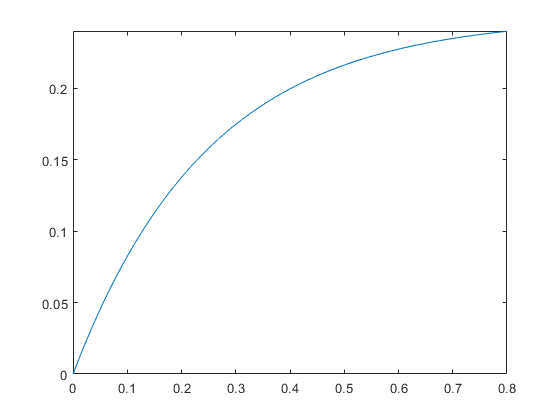

%3a

y = @(t) u(t)/4 - exp(-4*t)/4;

fplot(y, [0,0.8])

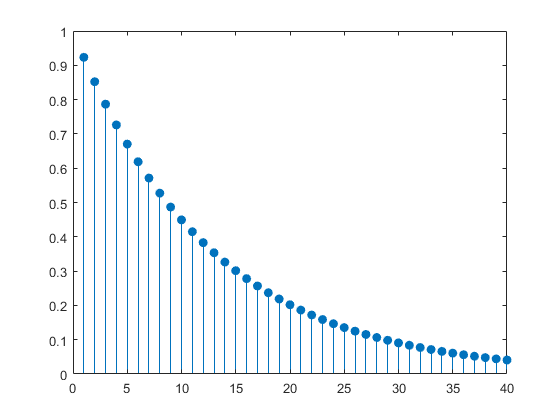

%4a
h = zeros(1, 40);

for n = 1:40
    h(n) = exp(-4*n*0.02);
end

stem(h, 'filled')

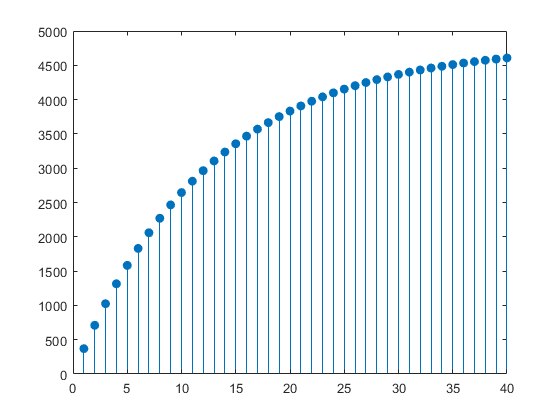


%4b
x = ones(1, 40);
y = conv(x, h);
y = y(1:40);
stem(y, 'filled'); 

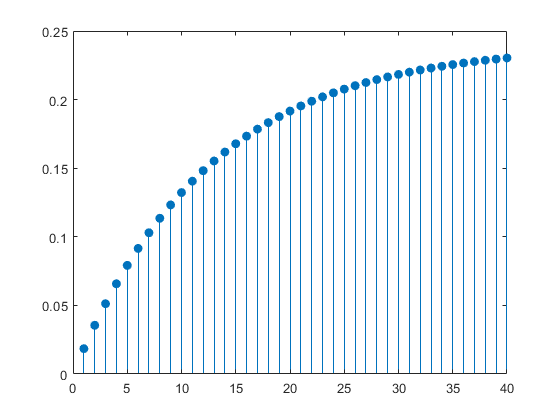


%5b

y = 0.02*conv(x, h); %multipliceras med Ts för att skala signalen rätt, annars går signalen upp till 
y = y(1:40);
stem(y, 'filled'); 

%6a-c
[y, fs] = audioread('nocturne.wav');

%soundsc(y, fs);

zero = zeros(1, 15);

h1 = [1 zero];
h = [h1 h1];
h = [h 1];

y =  fs * conv(y, h);
soundsc(y, fs); 

%6d
[y, fs] = audioread('nocturne.wav');

%soundsc(y, fs);

zero = zeros(1, 15);

h1 = [1 zero];
h = [h1 h1/2];
h = [h 1/4];

y =  0.02 * conv(y, h);
soundsc(y, fs); 

%7

load piano1.mat;

soundsc(y1, fs);

soundsc(y1, fs * 2); %ljudet spelas upp dubbelt så snabbt, resulterar i högre pitch

soundsc(y1, fs / 2); %ljudet spelas upp hälften så snabbt, resulterar i lägre pitch

%8

Fs = fs;        % Sampling frequency
T = 1/Fs;       % Sampling period
L = length(y1);  % Length of signal 
t = (0:L-1)*T;  % Time vector

% Plot in time domain
% plot(t, y1);
% xlabel('t (seconds)')
% ylabel('X(t)')

%Plot in Fourier domain
Y = fft(y1);    
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

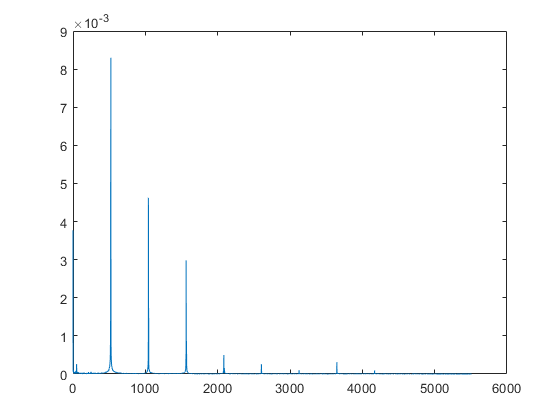

P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f, P1)



%checking if piano is tuned
delta_f = Fs / L

delta_f = 1.1024


[P1_max, index] = max(P1);

tone = f(index)

tone = 523.6351


lower_bound = tone - delta_f

lower_bound = 522.5327

upper_bound = tone + delta_f

upper_bound = 524.7375

y = 'y11'

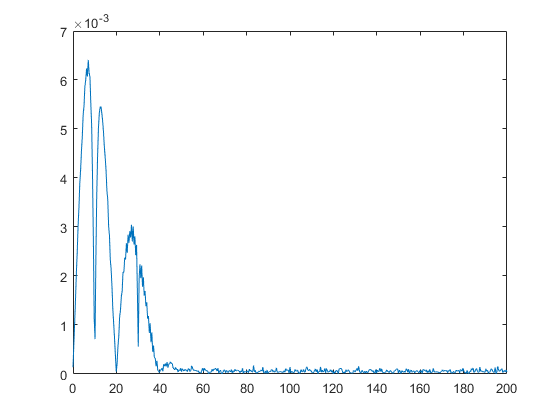

max_value = 7.0313

y = 'y12'

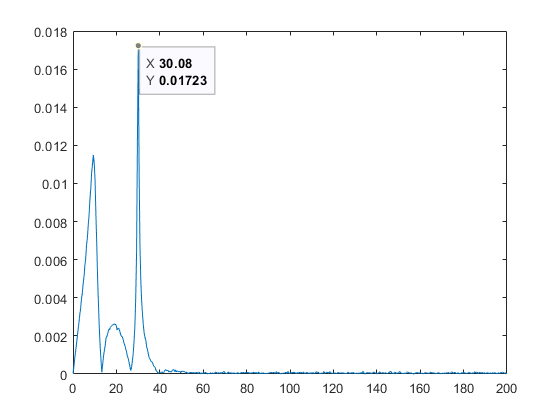

max_value = 30.0781

y = 'y21'

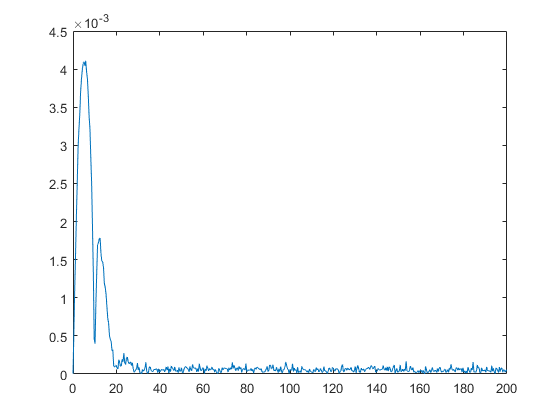

max_value = 5.8594

y = 'y22'

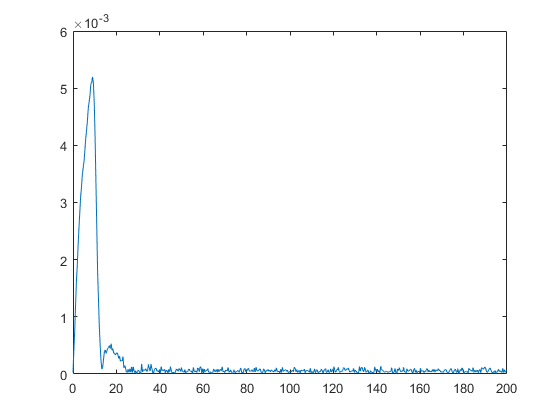

max_value = 8.9844

y = 'y31'

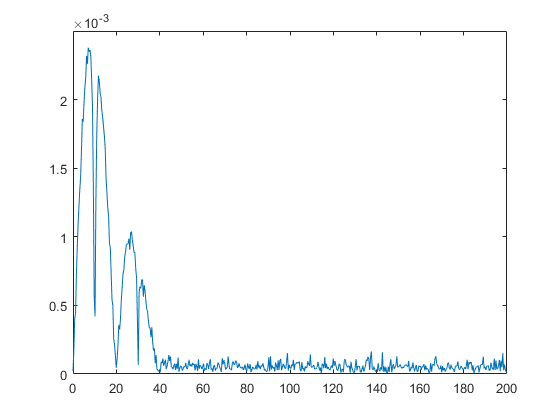

max_value = 7.0313

y = 'y32'

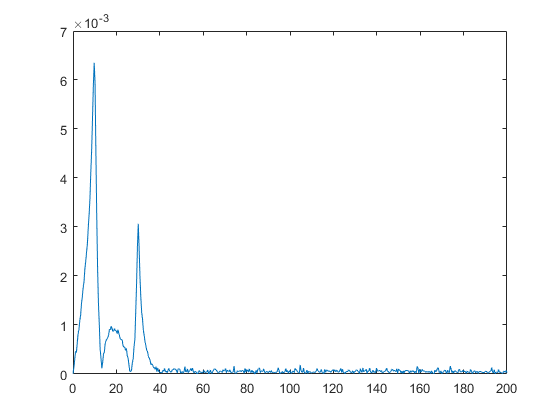

max_value = 9.7656

%9
load balk.mat

M = containers.Map({'y11', 'y12', 'y21', 'y22', 'y31', 'y32'}, ...
    {y11, y12, y21, y22, y31, y32});


for k = keys(M)
    thisfig = figure();
    
    y = k{1}
    
    Fs = fs;        % Sampling frequency
    T = 1/Fs;       % Sampling period
    L = length(M(y));  % Length of signal 
    %t = (0:L-1)*T;  % Time vector
    
    Y = fft(M(y));
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    f = Fs*(0:(L/2))/L;
    plot(f, P1)
    [P1_value, index] = max(f);
    max_value = f(index)
    
end 

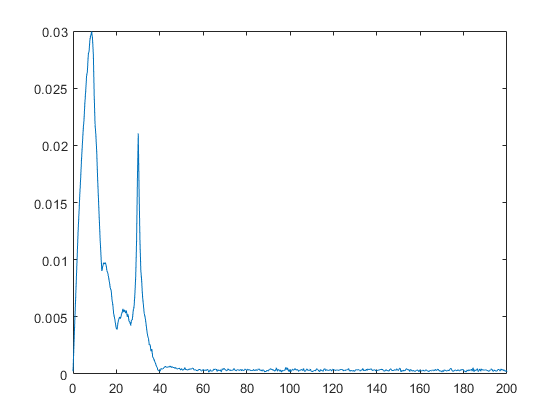

%9c
M = containers.Map({'y11', 'y12', 'y21', 'y22', 'y31', 'y32'}, ...
    {y11, y12, y21, y22, y31, y32});


plotsum = zeros(1,513);
for k = keys(M)
    
    
    y = k{1};
    
    Fs = fs;        % Sampling frequency
    T = 1/Fs;       % Sampling period
    L = length(M(y));  % Length of signal 
    %t = (0:L-1)*T;  % Time vector
    
    Y = fft(M(y));
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    f = Fs*(0:(L/2))/L;
    %plot(f, P1)
    
    plotsum = plotsum + P1;
end 

thisfig = figure();
plot(f, plotsum)

load phonenumber.mat

Fs = fs;        % Sampling frequency
T = 1/Fs;       % Sampling period
L = length(y);  % Length of signal 
t = (0:L-1)*T;  % Time vector
index = interp1(t,1:length(t),1.48,'nearest')

index = 8160

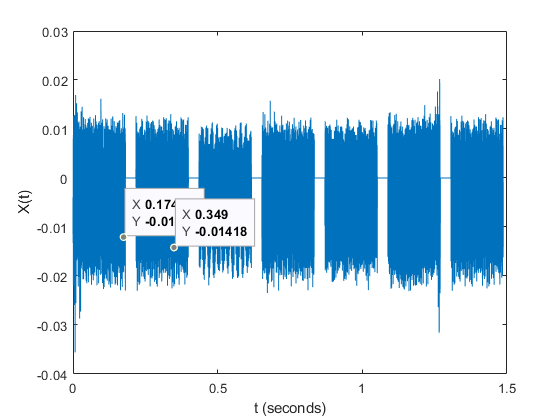



% Plot in time domain
plot(t, y);
xlabel('t (seconds)')
ylabel('X(t)')

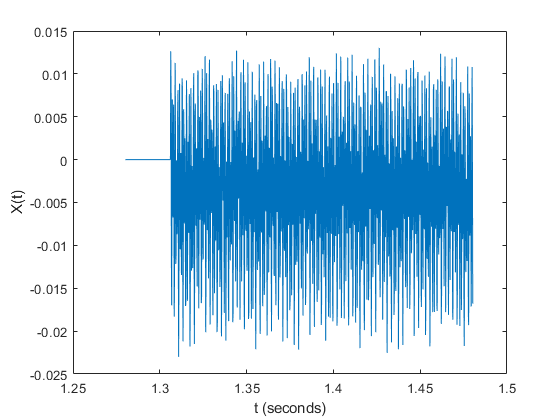


index1 = 7057;
index2 = 8160;

Fs = fs;        % Sampling frequency
T = 1/Fs;       % Sampling period
L = index2 - index1;  % Length of signal 
t = (index1:index2)*T;  % Time vector



% Plot in time 
plot(t, y(index1:index2));
xlabel('t (seconds)')
ylabel('X(t)')


Y = fft(y(index1:index2));
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

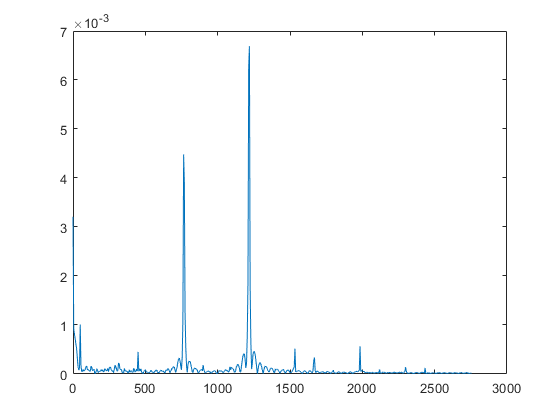

P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f, P1)